irr_vs_fir: script to compare IIR and FIR filters dimensions for similar frequency response.

Version: 001

Date:    2020/04/21

Author:  Rodrigo Gonzalez <rodralez@frm.utn.edu.ar>

URL:     https://github.com/rodralez/td3

URL:     https://github.com/rodralez/control

clc
clear
close all

## FIR design

% fir_kaiser_3400_44100: Low-pass FIR filter, Kaiser window.

Hd_fir = fir_kaiser_3400_44100; 

fir_coeff = Hd_fir.coefficients; %El kaiser tiene una caida un poco mas abrupta. Menos ripple en la banda pasante y más en la atenuada que el eliptico

## IIR design

% iir_elliptic_3400_44100: funcion que disena un filtro IIR a partir de
% filtro analogico eliptico

Hd_iir = iir_elliptic_3400_44100;

iir_coeff = Hd_iir.coefficients; %Subir ripple y/o Astop --> atenuacion menos abruta

## Compare both filters

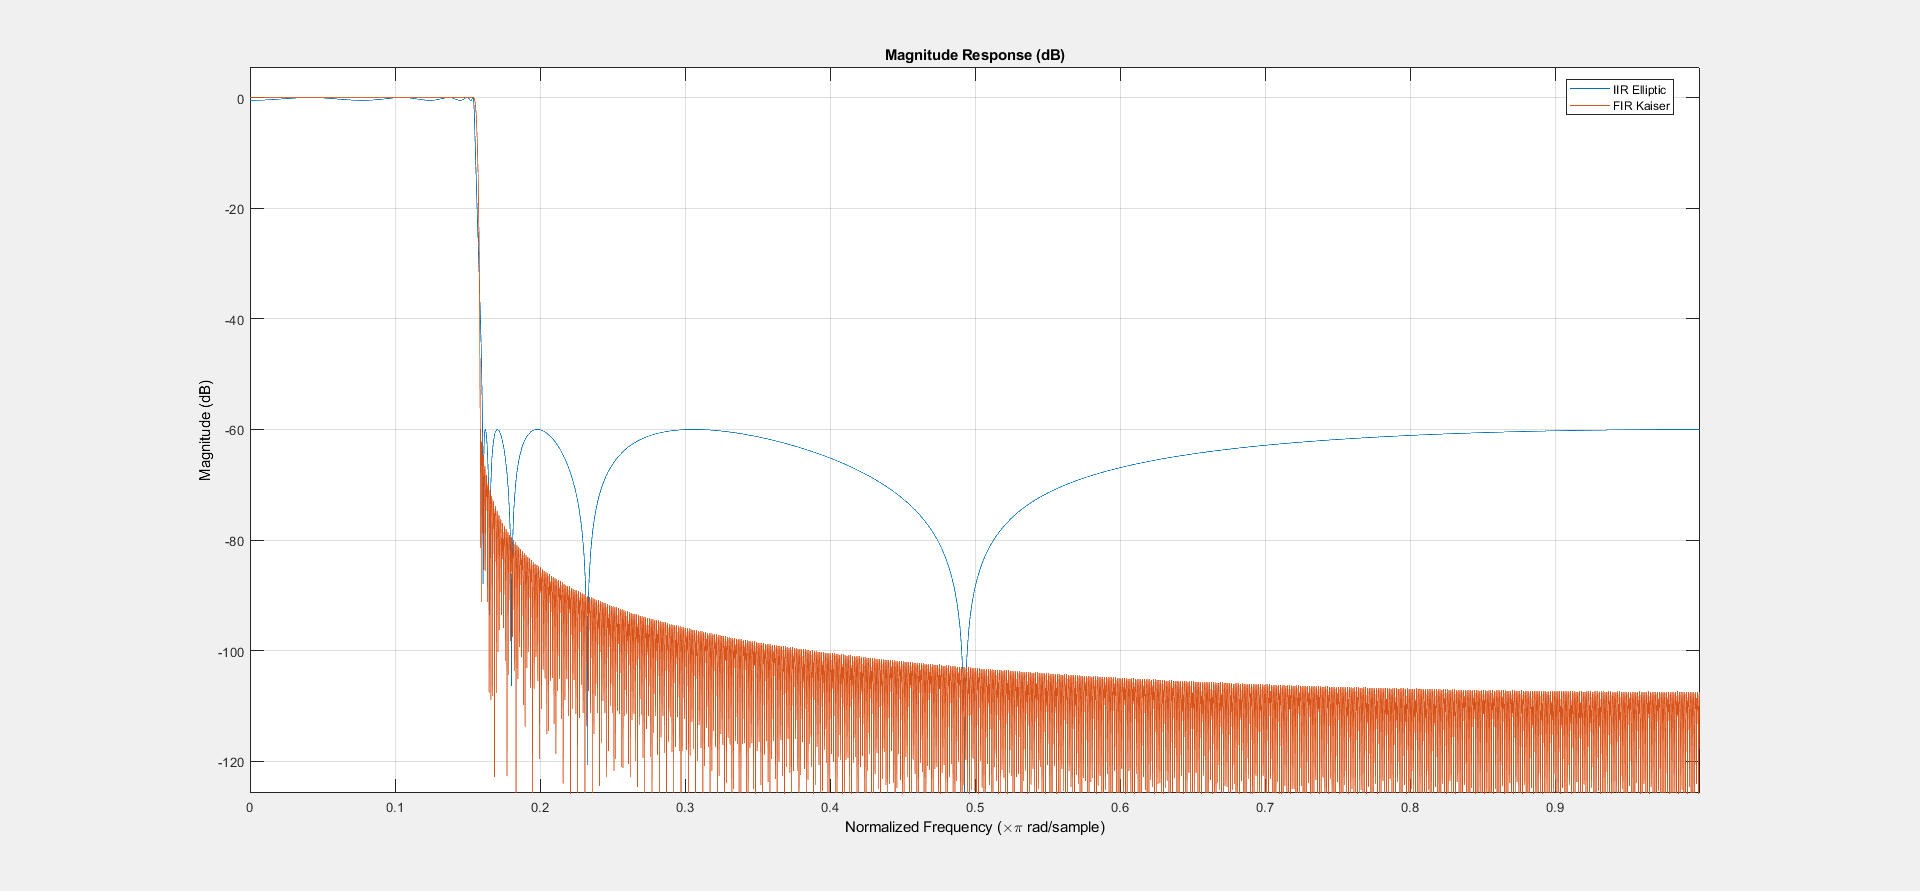

% fvtool: filter visualization tool

hfvt = fvtool(Hd_iir, Hd_fir, 'Analysis','Magnitude');
legend(hfvt,'IIR Elliptic', 'FIR Kaiser')

## Compare both filters in Phase

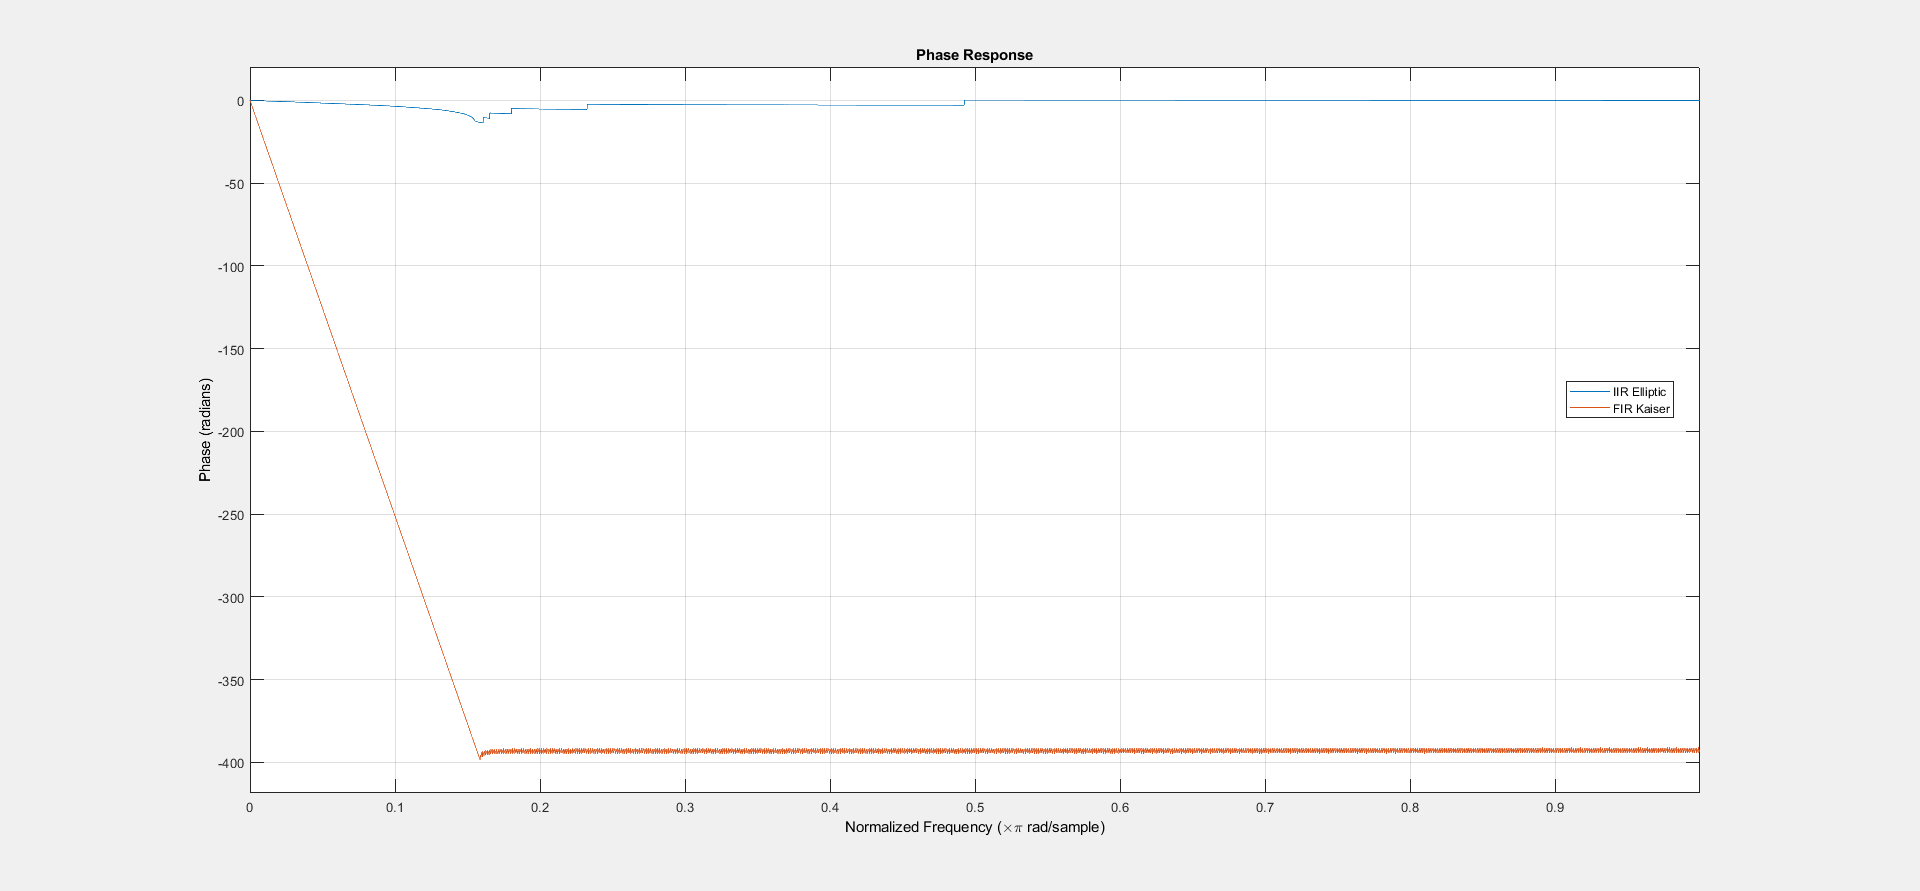

% fvtool: filter visualization tool

hfvt = fvtool(Hd_iir, Hd_fir, 'Analysis','Phase');
legend(hfvt,'IIR Elliptic', 'FIR Kaiser') %Kaiser super atrasado

## Filters dimensions

fir_dim = size(Hd_fir.Numerator);
iir_dim = size(Hd_iir.sosMatrix);

fprintf ('FIR filter dimension is [%d %d]', fir_dim(1), fir_dim(2)) % Como necesita 1600 muestras, es lento.

FIR filter dimension is [1 1600]

fprintf ('IIR filter dimension is [%d %d]', iir_dim(1), iir_dim(2)) % 6 muestras necesita, es más rápido a costa de tener ripple mas pronunciado

IIR filter dimension is [5 6]